# Boundary effect RSA (updata 2023/11/1) 

This updata mainly focus on the influence of boundary conditions on the following two aspects

- obj2seq 

- hippocampus wavlet

## Parameter Setting

subject ='Group';
plot_window=[1 25 1920 1080];
home_dir = '/bigvault/Projects/seeg_pointing';
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';

index = [7,13,25,31,43,49];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

## obj2sequence: boundary vs boundary

% load data
load(([group_dir,'rsa_obj2seq_bd.mat']))
% condition
obj2seq_bd_all = squeeze(mean(cell2matrix(cellmerge(rsa_group.bd,2)),3));
obj2seq_non_bd_all = squeeze(mean(cell2matrix(cellmerge(rsa_group.non_bd,2)),3));
% position
obj2seq_bd = squeeze(mean(cell2matrix(cellmerge(rsa_group.bd(:,[7,13]),2)),3));
obj2seq_non_bd = squeeze(mean(cell2matrix(cellmerge(rsa_group.non_bd(:,[7,13]),2)),3));
obj2seq_bd_pre = squeeze(mean(cell2matrix(cellmerge(rsa_group.bd(:,[6,12]),2)),3));
obj2seq_non_bd_pre = squeeze(mean(cell2matrix(cellmerge(rsa_group.non_bd(:,[6,12]),2)),3));

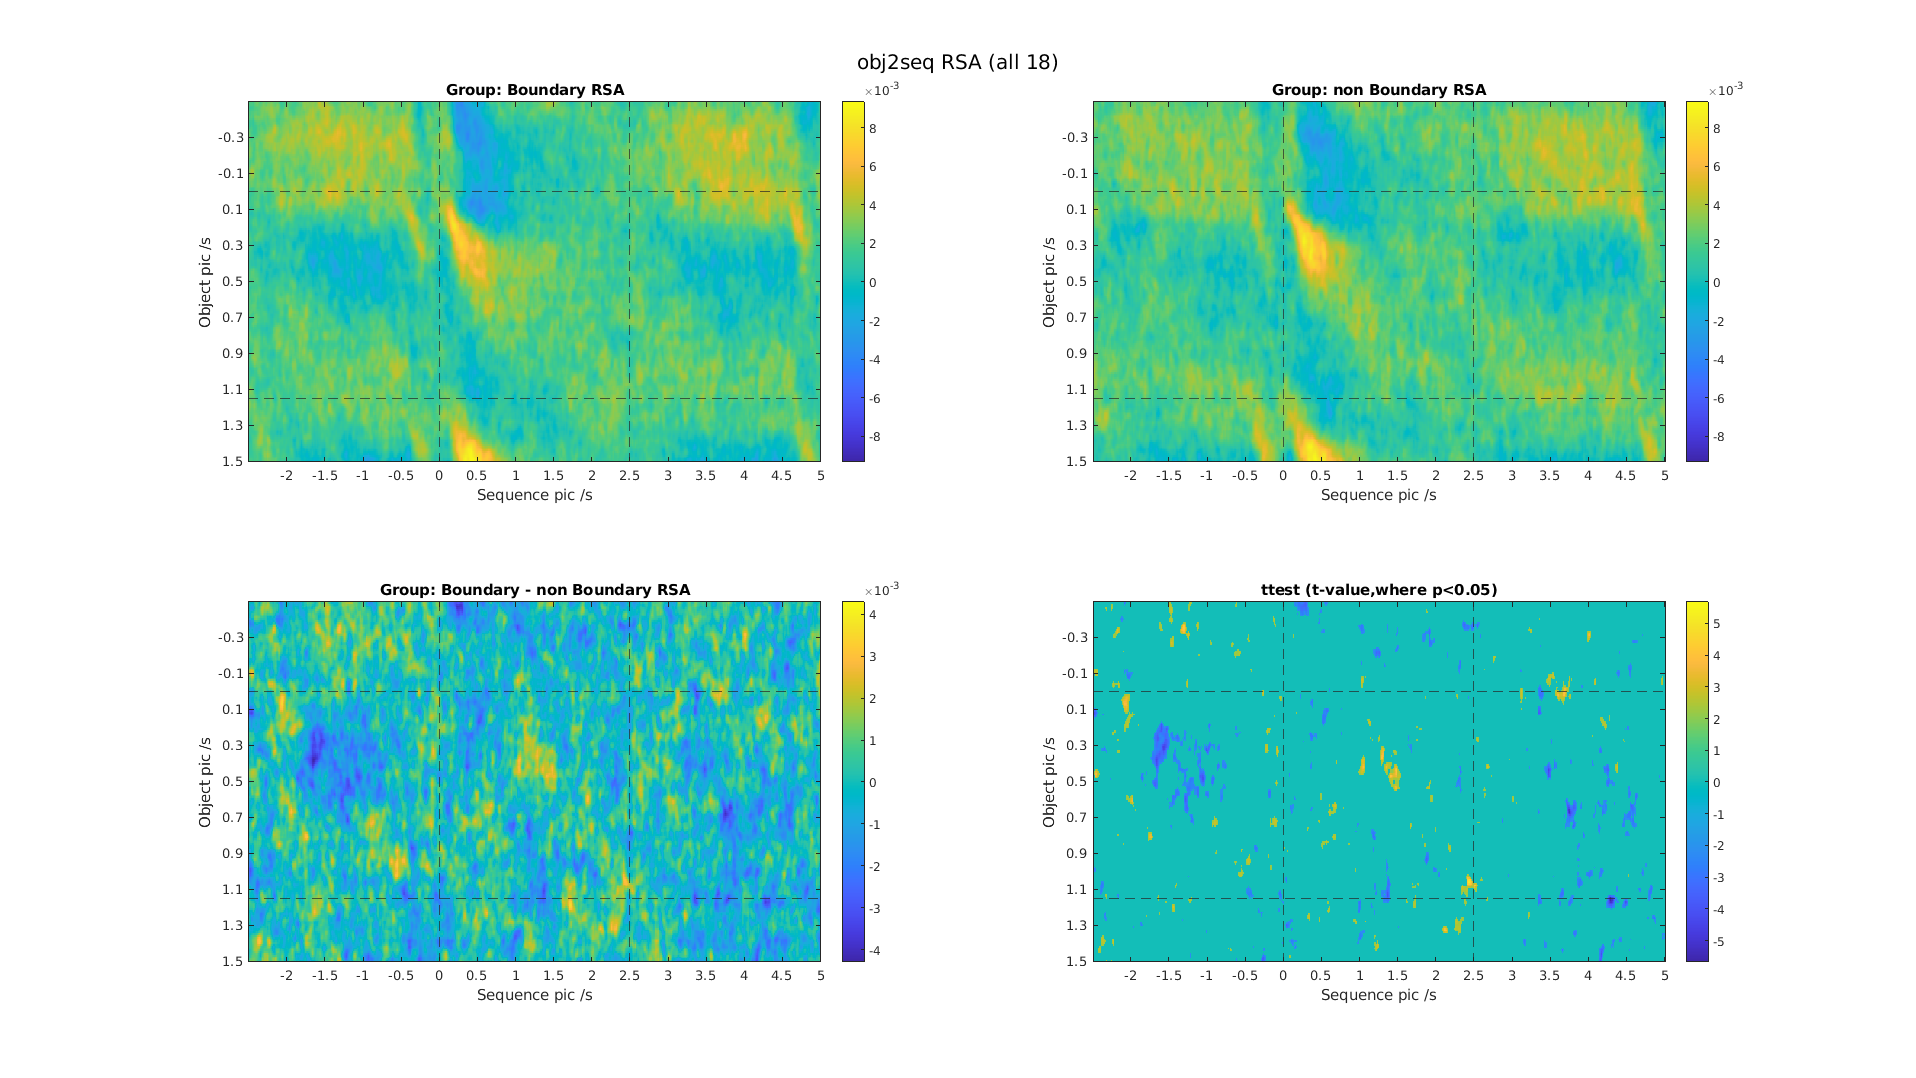

% plot obj2seq RSA in Boundary-non Boundary condition
plt_rsa_sd(obj2seq_bd_all,obj2seq_non_bd_all,'obj2seq')
subplot(2,2,1);title([subject,': Boundary RSA'])
subplot(2,2,2);title([subject,': non Boundary RSA'])
subplot(2,2,3);title([subject,': Boundary - non Boundary RSA'])
sgtitle('obj2seq RSA (all 18)')

% plot obj2seq RSA in Boundary-non Boundary position
plt_rsa_sd(obj2seq_bd,obj2seq_non_bd,'obj2seq')

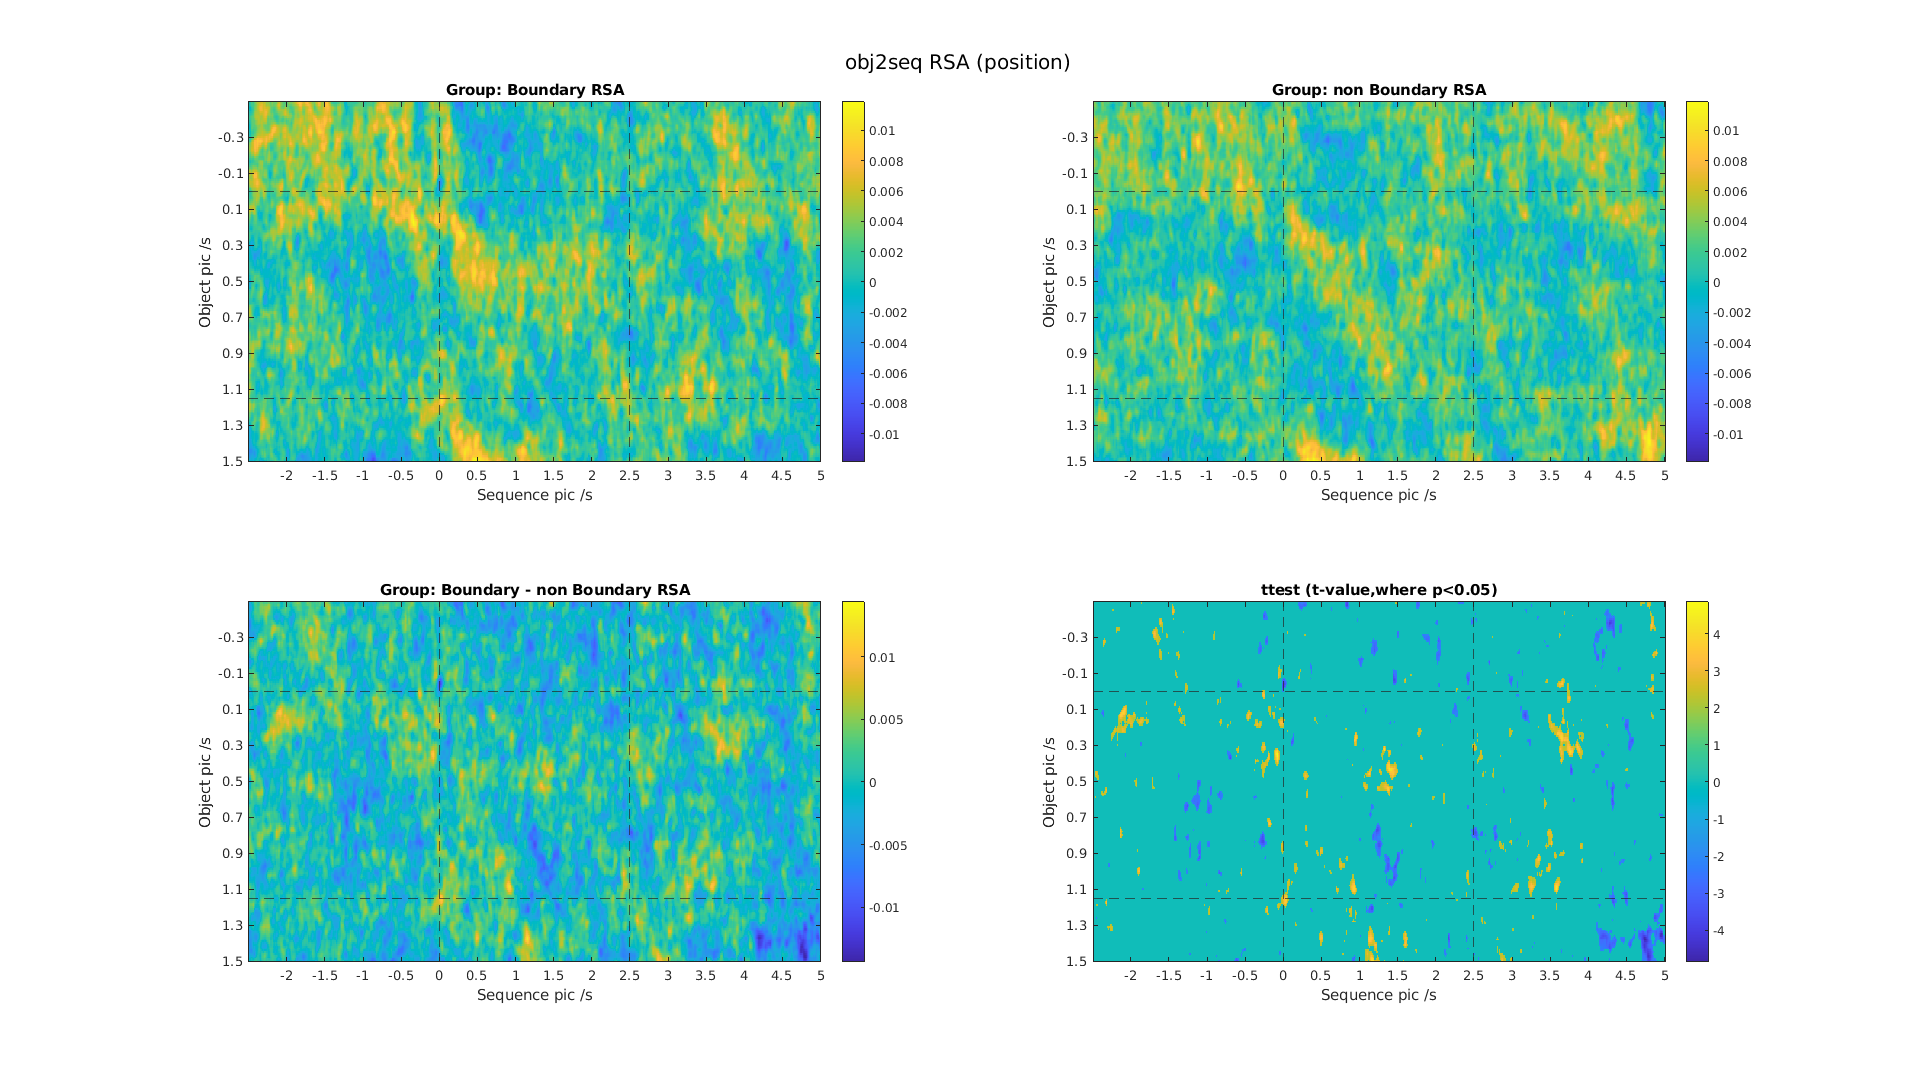

subplot(2,2,1);title([subject,': Boundary RSA'])
subplot(2,2,2);title([subject,': non Boundary RSA'])
subplot(2,2,3);title([subject,': Boundary - non Boundary RSA'])
sgtitle('obj2seq RSA (position)')

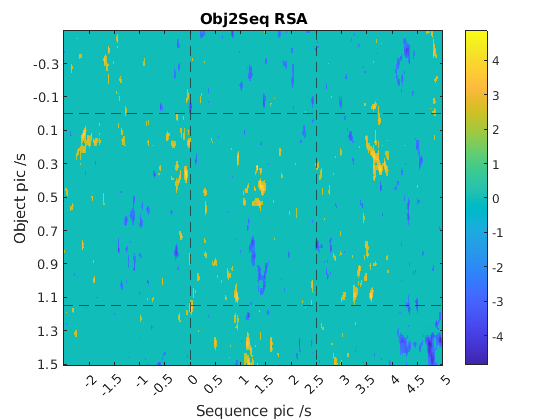

ans = 4.8577

% calculate ttest and mask(ttest)  position
[h_ttest,p_ttest,t_ttest]=ttest_2d(obj2seq_bd,obj2seq_non_bd);
ttest_result = h_ttest.*t_ttest;
figure;plt_imagesc(ttest_result,'obj2seq')

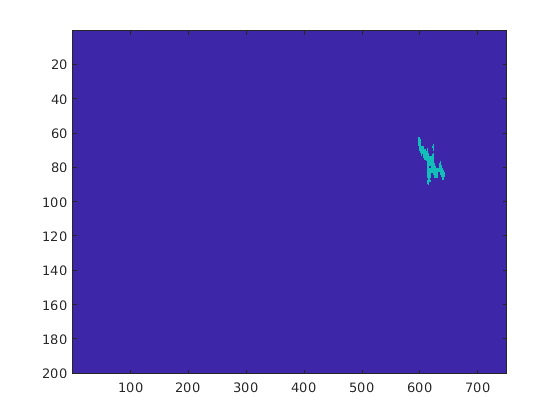

CC = bwconncomp(h_ttest);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = NaN(size(h_ttest));
mask(CC.PixelIdxList{1, cc_idx(2)}) = 1;
figure;imagesc(mask)

mask(isnan(mask)) = 0;
mask_ttest = mask;

% permutest position  % zoom in 
tic
[clusters_perm, p_perm, t_sums_perm, permutation_distribution ] = permutest(obj2seq_bd(51:165,501:700,:),obj2seq_non_bd(51:165,501:700,:),true,0.05,10000);
toc

Elapsed time is 96.371119 seconds.


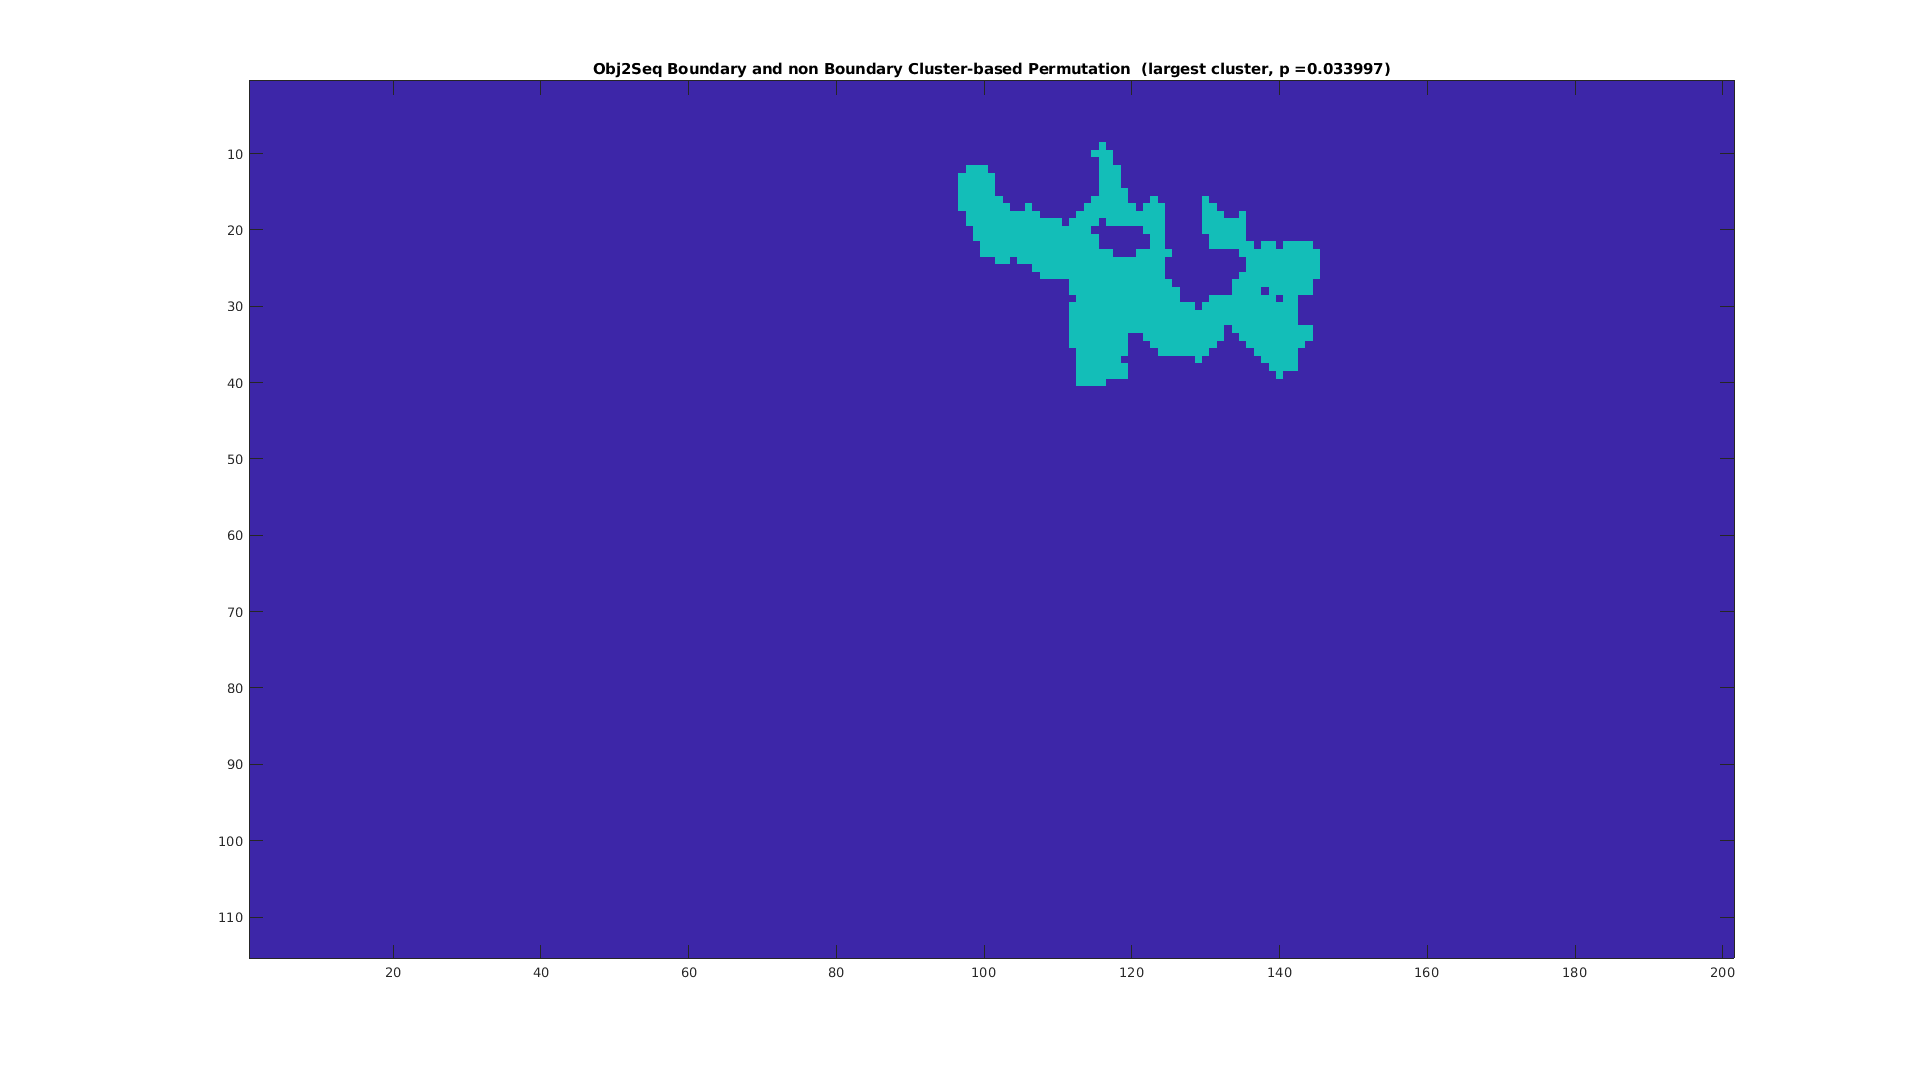

% permutest p=0.05
mask = NaN(size(obj2seq_bd(51:165,500:700,1)));
mask(clusters_perm{1, 1}) = 1;
figure;imagesc(mask)
title(['Obj2Seq Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(p_perm(1)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% plot mean value in each mask  condition ttest
obj2seq_bd_mask = obj2seq_bd.*mask_ttest;
obj2seq_non_bd_mask = obj2seq_non_bd.*mask_ttest;
mask_bd = squeeze(mean(obj2seq_bd_mask, [1 2], 'omitnan'));
mask_non_bd = squeeze(mean(obj2seq_non_bd_mask, [1 2], 'omitnan'));
figure
clim = [-0.008,0.008];
subplot(2,2,1)
imagesc(mean(obj2seq_bd_mask(60:100,590:650,:),3))
title('Boundary in mask')
caxis(clim)
colorbar()
subplot(2,2,2)
imagesc(mean(obj2seq_non_bd_mask (60:100,590:650,:),3))
title('non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,2,3)
plt_box_line([mask_bd,mask_non_bd],{'boundary','non boundary'})
title('Mask')
subplot(2,2,4)
plt_imagesc(mask,'obj2seq')

ans = 2

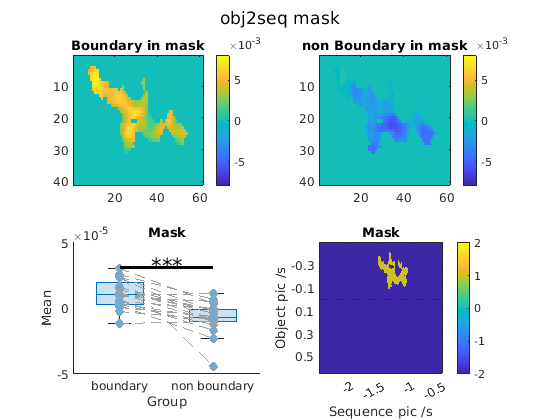

title('Mask')
sgtitle('obj2seq mask')

% anova   position(2,[boundary, non_boundary])*position(2,[pre,bd])
obj2seq = cat(3, obj2seq_bd,obj2seq_bd_pre,obj2seq_non_bd,obj2seq_non_bd_pre);
condition  = reshape(repmat([1,1,2,2], 20, 1),[],1);
position  = reshape(repmat([1,2,1,2], 20, 1),[],1);
p2=[];
for i = 1:size(obj2seq,1)
    for j=1:size(obj2seq,2)
        p2(i,j,:) = anovan(squeeze(obj2seq(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

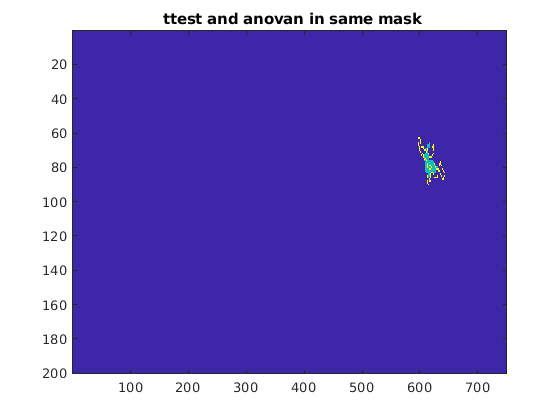

% mask combain ttest and anova
p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
CC = bwconncomp(anova_condition);
BW_ttest = bwperim(mask_ttest);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(4)}) = 1;
figure;imagesc(max(mask,double(BW_ttest)*2))
title(' ttest and anovan in same mask')

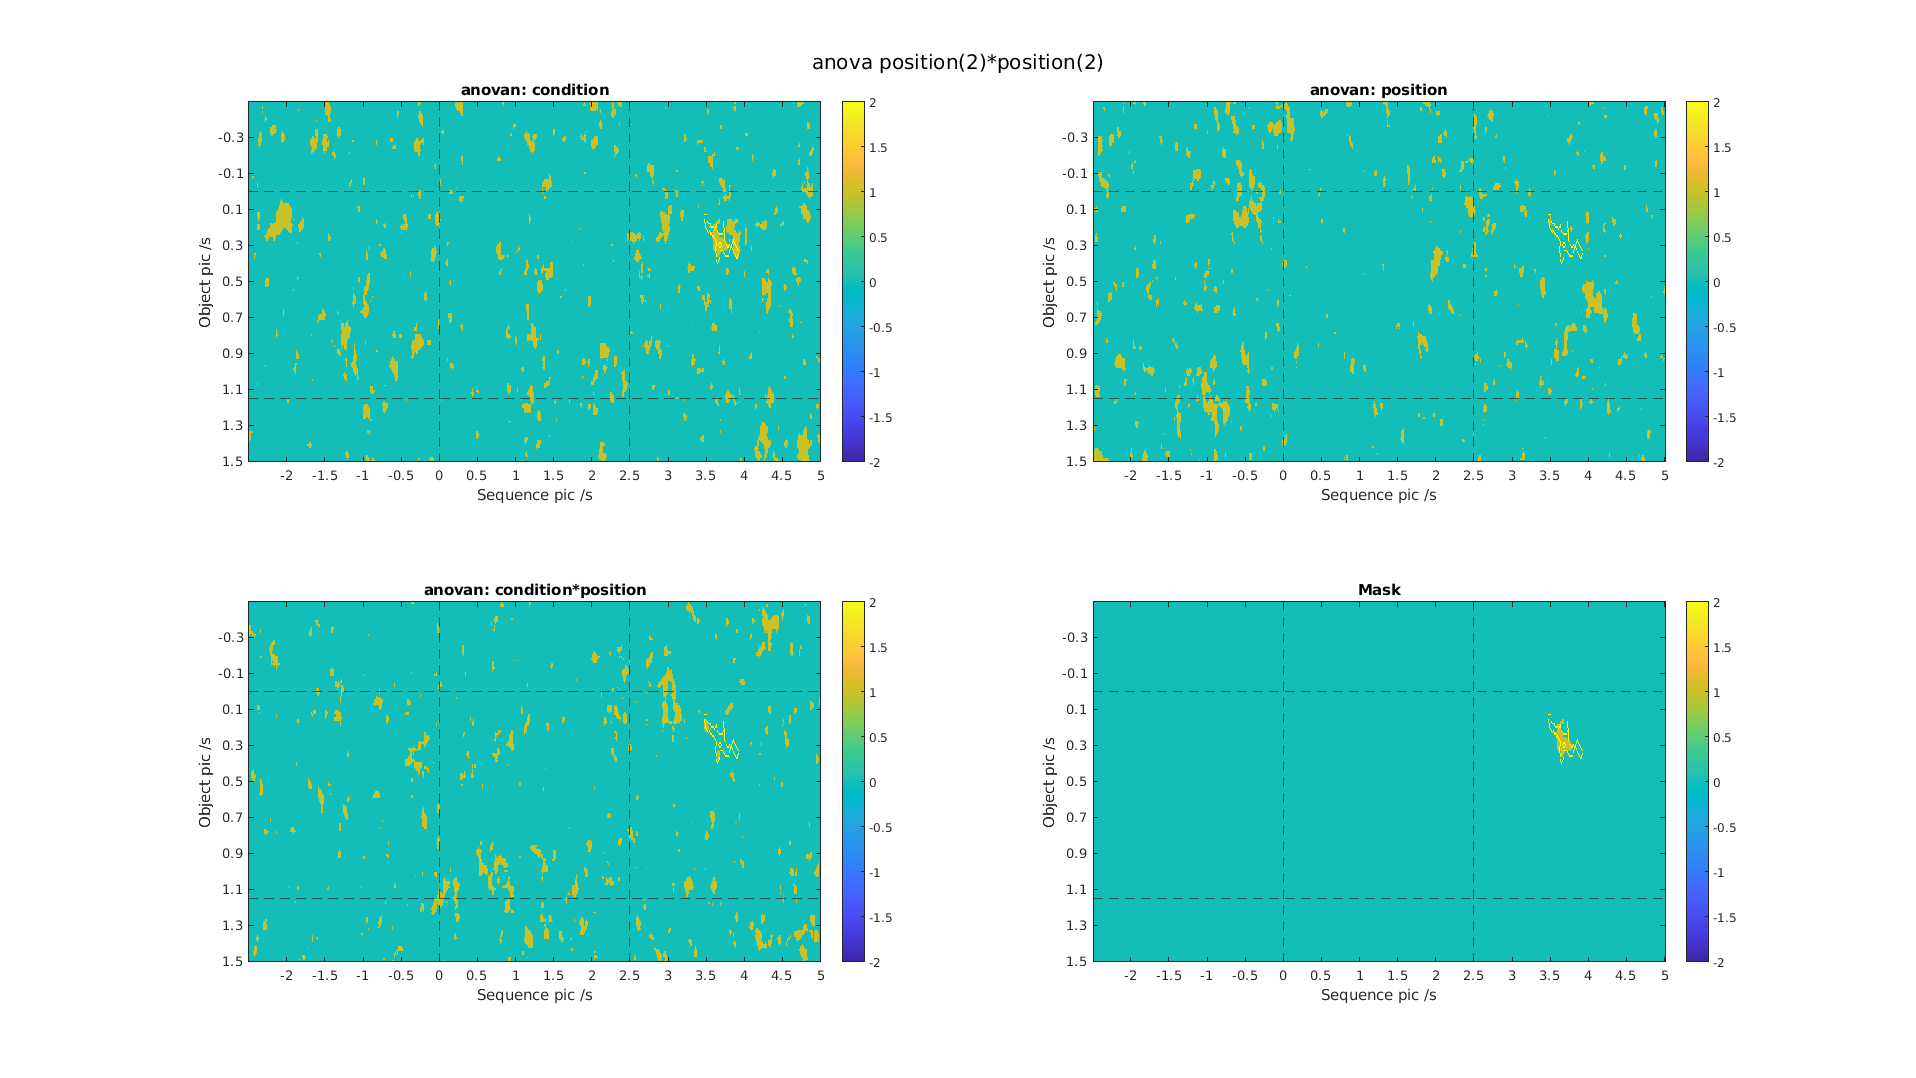

% plot anova result condition
p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
BW_ttest = bwperim(mask_ttest);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
        plt_imagesc(max(a(:,:,i),double(BW_ttest)*2),'obj2seq');
        title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask,double(BW_ttest)*2),'obj2seq');
        title('Mask')
    end
end
sgtitle('anova position(2)*position(2)')
set(gcf, 'Position', [1 25 1920 1080]);

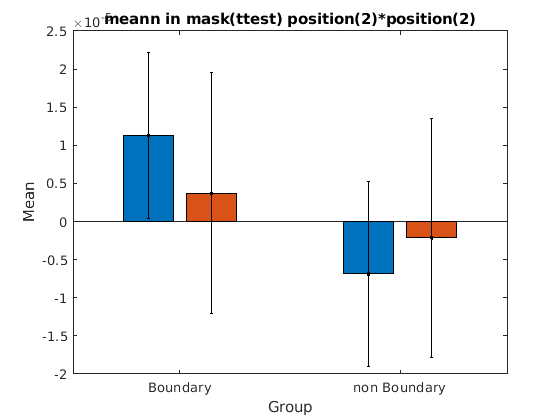

% plot anova result condition(anova 2*2, mask ttest)
data = [];
data(1,1,:) = squeeze(mean(mean(obj2seq_bd.*mask_ttest,1),2));
data(1,2,:) = squeeze(mean(mean(obj2seq_bd_pre.*mask_ttest,1),2));
data(2,1,:) = squeeze(mean(mean(obj2seq_non_bd.*mask_ttest,1),2));
data(2,2,:) = squeeze(mean(mean(obj2seq_non_bd_pre.*mask_ttest,1),2));
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(2)')

% anova   position(2,[boundary, non_boundary])*position(18,[1:18])
obj2seq=[];
for pici =1:18
obj2seq = cat(3, obj2seq,cell2matrix(rsa_group.bd(:,pici)));
end
for pici =1:18
obj2seq = cat(3, obj2seq,cell2matrix(rsa_group.non_bd(:,pici)));
end
condition  = reshape(repmat([1,2], 20*18, 1),[],1);
position  = reshape(repmat([1:18,1:18], 20, 1),[],1);

p18=[];
for i = 1:size(obj2seq,1)
    for j=1:size(obj2seq,2)
        p18(i,j,:) = anovan(squeeze(obj2seq(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

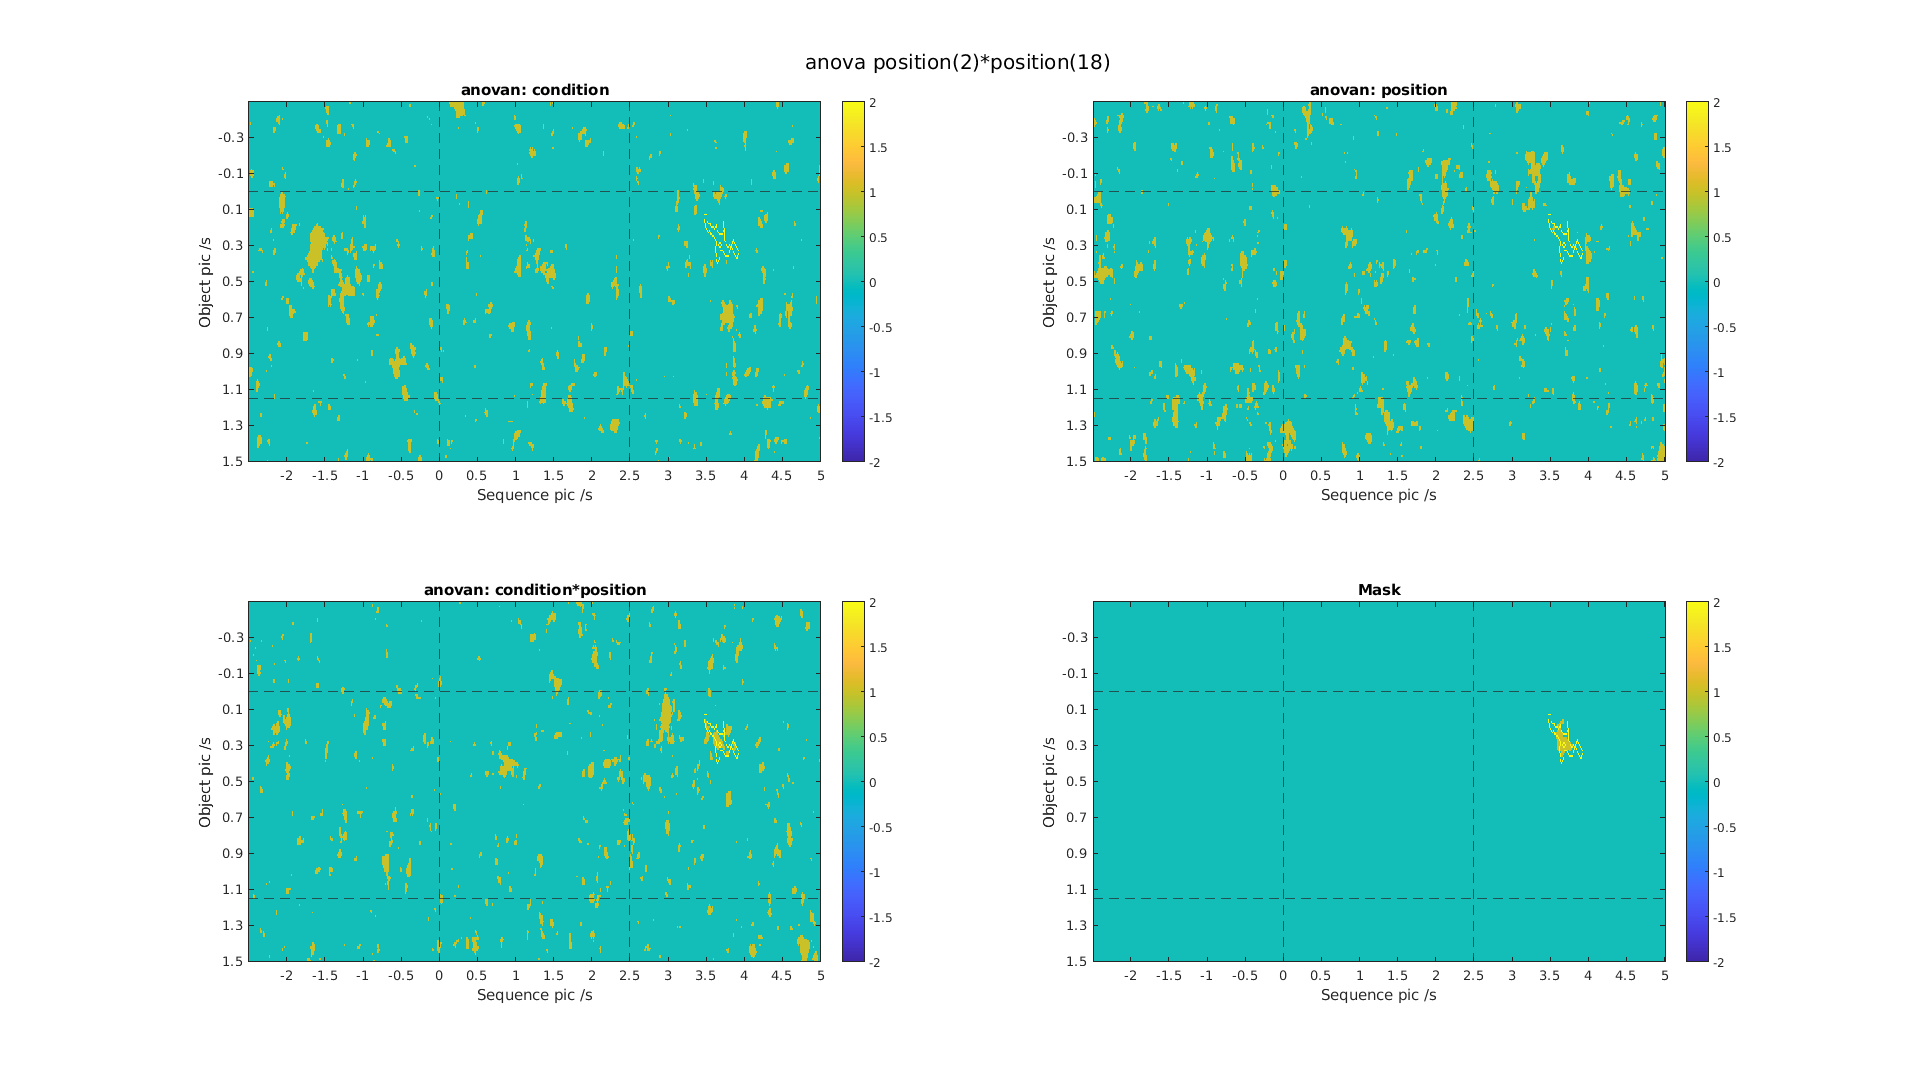

p=p18;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
BW_ttest = bwperim(mask_ttest);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
        plt_imagesc(max(a(:,:,i),double(BW_ttest)*2),'obj2seq');
        title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask,double(BW_ttest)*2),'obj2seq');
        title('Mask')
    end
end
sgtitle('anova position(2)*position(18)')
set(gcf, 'Position', [1 25 1920 1080]);

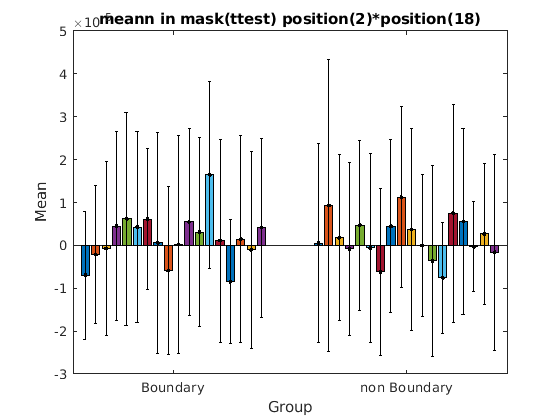

% plot anova result condition(anova 2*18, mask ttest)
data = [];
for pici=1:18
    data(1,pici,:) = squeeze(mean(mean(cell2matrix(rsa_group.bd(:,pici)).*mask_ttest,1),2));
    data(2,pici,:) = squeeze(mean(mean(cell2matrix(rsa_group.non_bd(:,pici)).*mask_ttest,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(18)')

% anova   position(2,[boundary, non_boundary])*position(6,[1:6])
obj2seq=[];
for pici =1:6
    temp = cell2matrix(cellmerge(rsa_group.bd(:,[pici,pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    obj2seq = cat(3, obj2seq,temp);
end
for pici =1:6
    temp = cell2matrix(cellmerge(rsa_group.non_bd(:,[pici,pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    obj2seq = cat(3, obj2seq,temp);
end
condition  = reshape(repmat([1,2], 20*6, 1),[],1);
position  = reshape(repmat([1:6,1:6], 20, 1),[],1);

p6=[];
for i = 1:size(obj2seq,1)
    for j=1:size(obj2seq,2)
        p6(i,j,:) = anovan(squeeze(obj2seq(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

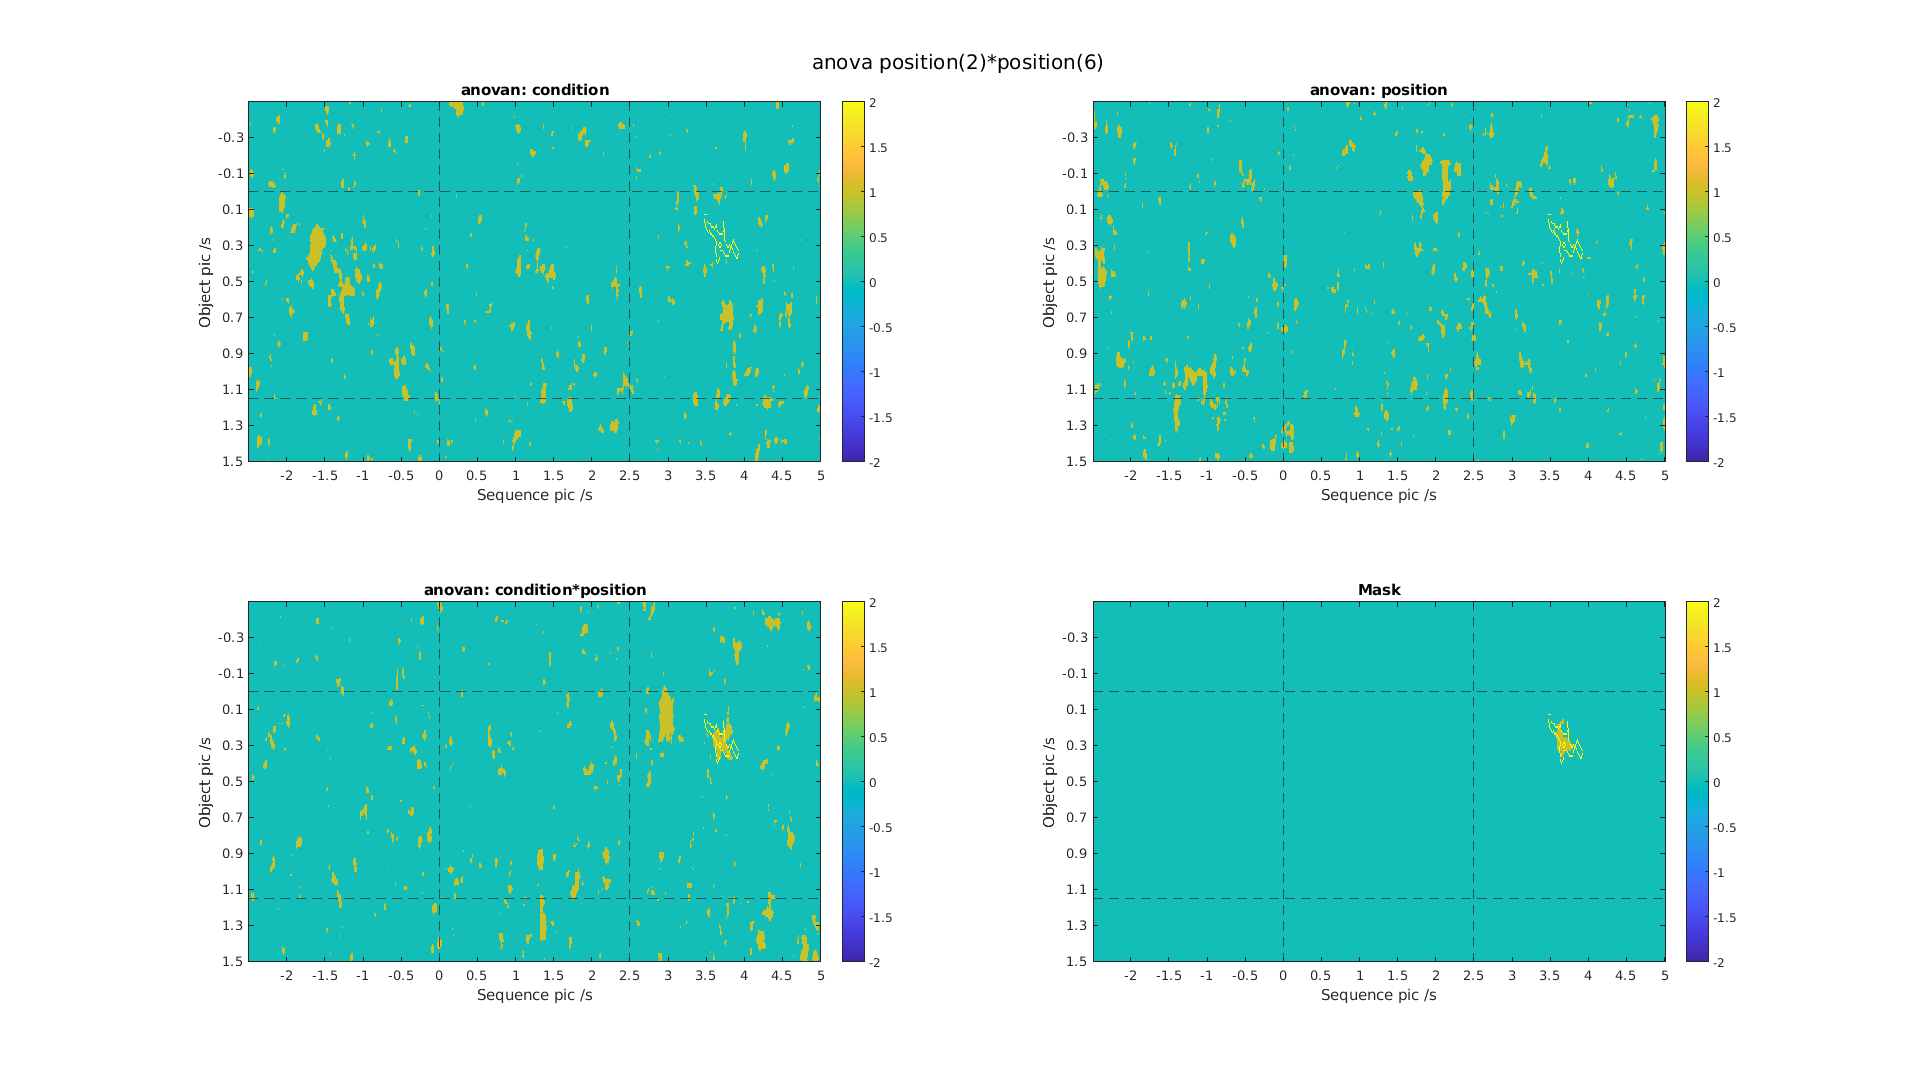

p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
BW_ttest = bwperim(mask_ttest);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
        plt_imagesc(max(a(:,:,i),double(BW_ttest)*2),'obj2seq');
        title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask,double(BW_ttest)*2),'obj2seq');
        title('Mask')
    end
end
sgtitle('anova position(2)*position(6)')
set(gcf, 'Position', [1 25 1920 1080]);

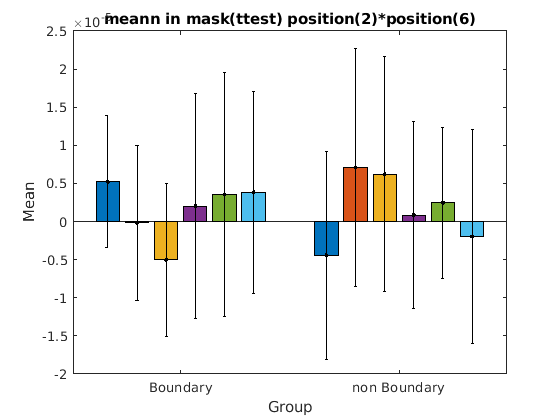

% plot anova result condition(anova 2*6, mask ttest) 3 turns
data = [];
for pici=1:6
    temp = cell2matrix(cellmerge(rsa_group.bd(:,[pici,pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    data(1,pici,:) = squeeze(mean(mean(temp.*mask_ttest,1),2));
    
    temp = cell2matrix(cellmerge(rsa_group.non_bd(:,[pici,pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    data(2,pici,:) = squeeze(mean(mean(temp.*mask_ttest,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')

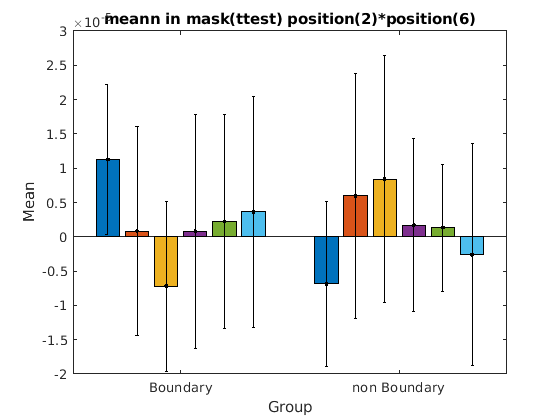

% plot anova result condition(anova 2*6, mask ttest)  2 turns
data = [];
for pici=1:6
    temp = cell2matrix(cellmerge(rsa_group.bd(:,[pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    data(1,pici,:) = squeeze(mean(mean(temp.*mask_ttest,1),2));
    
    temp = cell2matrix(cellmerge(rsa_group.non_bd(:,[pici+6,pici+12]),2));
    temp = squeeze(mean(temp,3));
    data(2,pici,:) = squeeze(mean(mean(temp.*mask_ttest,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')

% 
temp1 = squeeze(data(1,1,:));
temp2 = squeeze(mean(data(1,[2,3,4],:),2));
temp3 = squeeze(mean(data(1,[5,6],:),2));

temp4 = squeeze(data(2,1,:));
temp5 = squeeze(mean(data(2,[2,3,4],:),2));
temp6 = squeeze(mean(data(2,[5,6],:),2));

[~,p] = ttest(temp1,temp2)

p = 4.0598e-04

[~,p] = ttest(temp2,temp3)

p = 0.1454

ttest(temp3,temp6)

ans = 0